s.N = 1024;
s.Fs = 240e6;
s.Ng = 32;
s.Midx = 4;
s.type = "QAM";
s.SNRdB = nan();
s.Fsr = s.Fs;

s.Nsym = 300;
s.Nsfd = 300;

s.beta = 0;
s.Fc = getClosestFch(11.775e9);
s.Fcr = s.Fc;
s.Tdur = 1/750;
s.tau = 0;
s.gutter = 1;
if(s.gutter == 1)
    Nd = s.N - 4;
else
    Nd = s.N;
end

x = randi([0 s.Midx-1],Nd,s.Nsym);
s.data = x;


% Estimation Of N:
Plot_One_Try = 1;
Plot_Expectation = 1;

% s.Nsym = 1000;
x = randi([0 s.Midx-1],Nd,s.Nsym);
s.data = x;
str1 = genStrlkFrame(s);

% str2 = circshift(str1,floor(length(str1)/2));
vec = xcorr(str1,str1);
[val1 , idx1] = max(vec);
vec(idx1) = 0;
[val2 , idx2] = max(vec);
secondLobeIdx = abs(idx2 - idx1)

secondLobeIdx = 1024

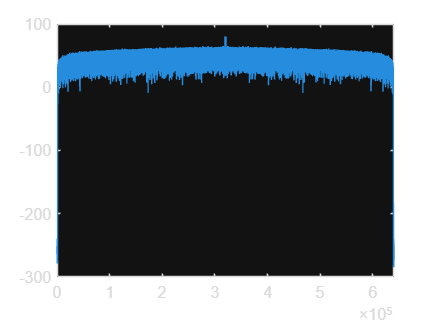

if(Plot_One_Try == 1)
    t = 1:length(vec);
    plot(t,mag2db(abs(vec)));
end


% The same Estimation using expectation functions
tries = 100;

vec = zeros(length(vec),1);
for i = 1:tries
    x = randi([0 s.Midx-1],Nd,s.Nsym);
    s.data = x;
    str1 = genStrlkFrame(s);
    vec = vec + xcorr(str1,str1);
end
[val1 , idx1] = max(vec);
vec(idx1) = 0;
[val2 , idx2] = max(vec);
secondLobeIdx = abs(idx2 - idx1)

secondLobeIdx = 1024

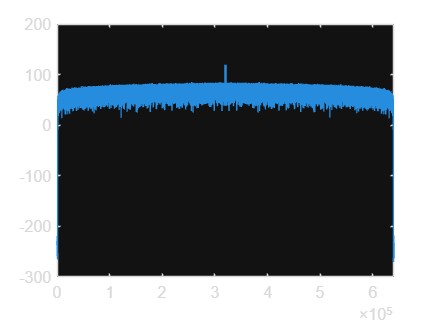


if(Plot_Expectation == 1)
    t = 1:length(vec);
    plot(t,mag2db(abs(vec)));
end

% Estimation of Tframe:
frames = 10;
x = randi([0 s.Midx-1],Nd,s.Nsym);
s.data = x;
str2 = genStrlkFrame(s);
for ii = 1:frames-1
    x = randi([0 s.Midx-1],Nd,s.Nsym);
    s.data = x;
    str2 = [str2;genStrlkFrame(s)];
end

% str2 = circshift(str1,floor(length(str1)/2));
vec = xcorr(str2,str2);
[val1 , idx1] = max(vec);
vec(idx1) = 0;
t = 1:length(vec);
[val2 , idx2] = max(vec);
vec(idx2) = 0;
vec(2*idx1 - idx2) = 0;
[val3 , idx3] = max(vec);
Tframe_Estimation = abs(idx3 - idx1)

Tframe_Estimation = 320000

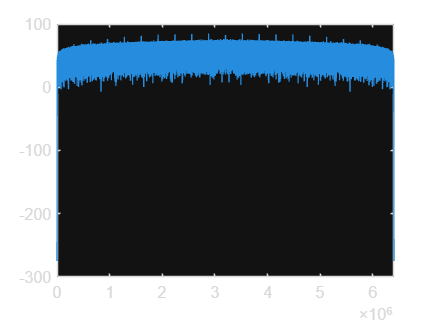

plot(t,mag2db(abs(vec)));

% Estimation of Ng:
N_Estimate = secondLobeIdx;

s.Nsym = 100;
x = randi([0 s.Midx-1],Nd,s.Nsym);
s.data = x;
str1 = genOFDM(s);
str1corr = zeros(length(str1),1);
for i = 1:100
    x = randi([0 s.Midx-1],Nd,s.Nsym);
    s.data = x;
    str1 = genOFDM(s);
    str1shifted = circshift(str1,N_Estimate);
    str1temp = zeros(length(str1),1);
    for iii = 1:length(str1)
        str1temp(iii) = conj(str1(iii))*str1shifted(iii);
    end
    str1corr = str1corr + str1temp;
end

veccorr = xcorr(str1corr,str1corr);
[val3 , idx3] = max(veccorr);
veccorr(idx3) = 0;
[val4 , idx4] = max(veccorr);
Ng_Estimate = abs(idx4 - idx3) - N_Estimate

Ng_Estimate = 32

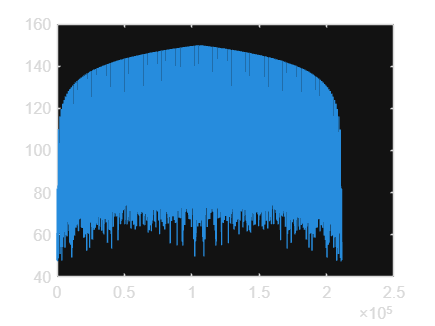


t = 1:length(veccorr);
plot(t,mag2db(abs(veccorr)));